# ENME462_Studio_1

TA: Xie Zheng

Research Focus: Vibration & Control 

Section 0101 Wed 2:00PM - 3:50PM, Section 0103 Friday 10:00AM - 11:50 AM

Office Hour: Friday 1:00PM - 2:00PM at 0103 ELG  

Github: [https://github.com/XieGT/Control_Studios](https://github.com/XieGT/Control_Studios)

Email: xiezheng@umd.edu

## Lapalce transformation, Partial fraction expansion, ODE

**1.1 Laplace transformation **


$$\mathcal{L}[f(t)]=F(s)=\int_{0-}^{\infty}f(t)e^{-st}dt$$



$$\mathcal{L}[\delta(t)]=1 \\
\mathcal{L}[u(t)]=\frac{1}{s}\\
\mathcal{L}[tu(t)]=\frac{1}{s^2}\\
\mathcal{L}[t^{n}u(t)]=\frac{n!}{s^{n+1}}\\
\mathcal{L}[e^{-at}u(t)]=\frac{1}{s+a}\\
\mathcal{L}[\sin(\omega t)]=\frac{\omega}{s^2+\omega^2}\\
\mathcal{L}[\cos(\omega t)]=\frac{s}{s^2+\omega^2}$$


syms t a omega n            % define the symbolic variable 
assume(n,'real');
assumeAlso(n,'positive');   % assume n is a real & positive number

laplace(t^0)               

$$ans = \frac{1}{s}$$

laplace(t)                  

$$ans = \frac{1}{s^{2}}$$

laplace(t^n)                

$$ans = \frac{\Gamma (n+1)}{s^{n+1}}$$

laplace(exp(-a*t))            

$$ans = \frac{1}{a+s}$$

laplace(sin(omega*t))       

$$ans = \frac{\omega }{\omega^{2}+s^{2}}$$

laplace(cos(omega*t)) 

$$ans = \frac{s}{\omega^{2}+s^{2}}$$

**1.2 Laplace transform theormes**

 Linearity theorem


$$\mathcal{L}[kf(t)]=kF(s) \qquad \mathcal{L}[f_{1}(t)+f_{2}(t)]=F_{1}(s)+ F_{2}(s)$$


Frequency shift theorem     Time shift theorem


$$\mathcal{L}[e^{-at}f(t)]=F(s+a) \qquad \mathcal{L}[f(t-T)]=e^{-sT}F(s)$$


Scaling theorem


$$ \mathcal{L}[f(at)]=\frac{1}{a}F(\frac{s}{a})$$


Differentiation theorem


$$\mathcal{L}[\frac{df}{dt}]=sF(s)-f(0_{-}) \qquad \mathcal{L}[\frac{d^{2}f}{dt^{2}}]=s^{2}F(s)-sf(0_{-})-f'({0_{-}})$$



$$\mathcal{L}[\frac{d^{n}f}{dt^{n}}]=s^{n}F(s)-\sum_{k=1}^{n}s^{n-k}f^{k-1}(0_{-})$$


Integration theorem


$$\mathcal{L}[\int_{0-}^{t}f(\tau)d\tau]=\frac{1}{s}F(s)$$


Final value theorem     Initial value theorem


$$f(\infty)=\lim_{s \rightarrow 0}sF(s) \qquad f(0+)=\lim_{s\rightarrow \infty}sF(s)$$


**2. Partial fraction exapansion**

***i) Steps for PFE***

*1) Check the degree of the numerator must be less than the degree of the denominator.*

*2) Factor out the denominator into 1st-order & 2nd-order rational factors.*

*3) Find numerator coefficients.*

**Example 1: **find the PFE of  $\frac{5x+7}{x^2+3x+2}$

step 1: $O(5x+7)<O(x^2+3x+2)$

step 2: $x^2+3x+2=(x+1)(x+2)$

step 3: $\frac{5x+7}{x^2+3x+2}=\frac{A}{x+1}+\frac{B}{x+2}$


$$5x+7=A(x+2)+B(x+1)$$


method 1:  Multiply both sides by the denominator and place the coefficients of the 

variable equal on both sides of the equation:


$$5x+7=(A+B)x+(2A+B)\\
 \left\{ \begin{array}{ll}
A+B=5 \\
2A+B=7\\
\end{array}\\
A=2 \qquad B=3$$


method 2: Carefully choosing values for x yields the values for A and B as follows:


$$x=-1,\rightarrow A=2\\
x=-2,\rightarrow B=3$$



$$\frac{5x+7}{x^2+3x+2}=\frac{2}{x+1}+\frac{3}{x+2}$$


MATLAB codes:

num = [5 7];                % coefficients of numerator
den = [1 3 2];              % coefficients of denominator
[r,p,k] = residue(num,den)  % r: residues, p: poles, k: direct quotient

r =      3
     2


p =     -2
    -1



k =

     []



***ii) Factors anticipated***

*1) For linear terms ax+b we have*


$$\frac{A}{ax+b}$$


*2) for quadratic terms (quadratics that don't have real roots)*


$$\frac{Ax+B}{ax^{2}+bx+c}$$


*3) for repeated roots (ax+b)^3*


$$\frac{A}{ax+b}+\frac{B}{(ax+b)^2}+\frac{C}{(ax+b)^3}$$


**Example 2: **Repeated roots

  
$$\frac{2x^2+1}{x^3-x^2-8x+12}=\frac{2x^2+1}{(x-2)^2(x+3)}=\frac{A}{x-2}+\frac{B}{(x-2)^2}+\frac{C}{x+3}$$


Matlab codes:

num = [2 0 1];
den = [1 -1 -8 12];
[r,p,k] = residue(num,den)

r =     0.7600
    1.2400
    1.8000


p =    -3.0000
    2.0000
    2.0000



k =

     []



**Example 3:** a simple root and a pair of comlex roots


$$\frac{x^2+1}{(x^2+x+2)(x+7)}=\frac{Ax+b}{x^2+x+2}+\frac{C}{x+7}$$


MATLAB code:

num = [1 0 1];
den = conv([1 1 2],[1 7]);  % conv: convolve 
[r,p,k] = residue(num,den)

r =    1.1364 + 0.0000i
  -0.0682 + 0.0430i
  -0.0682 - 0.0430i


p =   -7.0000 + 0.0000i
  -0.5000 + 1.3229i
  -0.5000 - 1.3229i



k =

     []



**Example 4:** Repeated complex roots


$$\frac{1}{(x^2+2x+5)^2(x-1)(x+2)}=\frac{Ax+B}{x^2+2x+5}+\frac{Cx+D}{(x^2+2x+5)^2}+\frac{E}{x-1}+\frac{F}{x+2}$$


MATLAB codes:

num = 1;
den = conv(conv([1 2 5],[1 2 5]),conv([1 -1],[1 2]));   
[r,p,k] = residue(num,den)

r =    0.0041 + 0.0106i
   0.0094 - 0.0031i
   0.0041 - 0.0106i
   0.0094 + 0.0031i
  -0.0133 + 0.0000i
   0.0052 + 0.0000i


p =   -1.0000 + 2.0000i
  -1.0000 + 2.0000i
  -1.0000 - 2.0000i
  -1.0000 - 2.0000i
  -2.0000 + 0.0000i
   1.0000 + 0.0000i



k =

     []



**Example 5:** Repeated  roots


$$\frac{1}{(x^2-3)^2}=\frac{1}{(x-\sqrt{3})^2(x+\sqrt{3})^2}=\frac{A}{(x-\sqrt{3})}+\frac{B}{(x-\sqrt{3})^2}+\frac{C}{(x+\sqrt{3})}+\frac{}{}+\frac{D}{(x+\sqrt{3})^2}$$


MATLAB codes:

num = 1;
den = conv([1 0 -3],[1 0 -3]);   
[r,p,k] = residue(num,den)

r =    -0.0481
    0.0833
    0.0481
    0.0833


p =     1.7321
    1.7321
   -1.7321
   -1.7321



k =

     []



**Example 6:**


$$\frac{2x-1}{(x+2)^2(x-3)}=\frac{A}{x+2}+\frac{B}{(x+2)^2}+\frac{C}{x-3}\\
2x-1=A(x+2)(x-3)+B(x-3)+C(x+2)^2$$


Method 1: 


$$2x-1=(A+C)x^2+(-A+B+4C)x+(-6A-3B+4C)$$



$$ \left\{ \begin{array}{ll}
A+C=0 \\
-A+B+4C=2\\
-6A-3B+4C=-1
\end{array}\\
A=-\frac{1}{5} \qquad B=1 \qquad C=\frac{1}{5}$$


Method 2: 


$$x=3,\rightarrow C=\frac{1}{5}\\
x=-2,\rightarrow B=1\\
x=0, \rightarrow  A=-\frac{1}{5}$$



$$\frac{2x-1}{(x+2)^2(x-3)}=\frac{-1/5}{x+2}+\frac{1}{(x+2)^2}+\frac{1/5}{x-3}\\
2x-1=A(x+2)(x-3)+B(x-3)+C(x+2)^2$$


MATLAB codes:

num = [2 -1];
den = conv(conv([1 2],[1 2]),[1 -3]);   
[r,p,k] = residue(num,den)

r =     0.2000
   -0.2000
    1.0000


p =     3.0000
   -2.0000
   -2.0000



k =

     []



**3. Solution to an ODE: A Mass-Sping System **

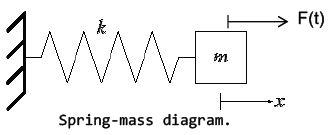

Equation of motion:


$$m\ddot{x}(t)+kx(t)=F(t)$$


***i) Hand calculation via convolution integral***


$$x(t)=\frac{1}{m\omega_n}\int_{0}^{t}F(\tau)\sin(\omega_n(t-\tau))d\tau$$


if F(t) is unit step signal


$$x(t)=\frac{1}{m\omega_n}\int_{0}^{t}1\sin(\omega_n(t-\tau))d\tau=\frac{1}{m\omega_n}\frac{1}{\omega_n}\cos(\omega_n(t-\tau))|_{0}^{t}\\
x(t)=\frac{1}{k}(1-\cos(\omega_nt))$$


Time response in MATLAB:

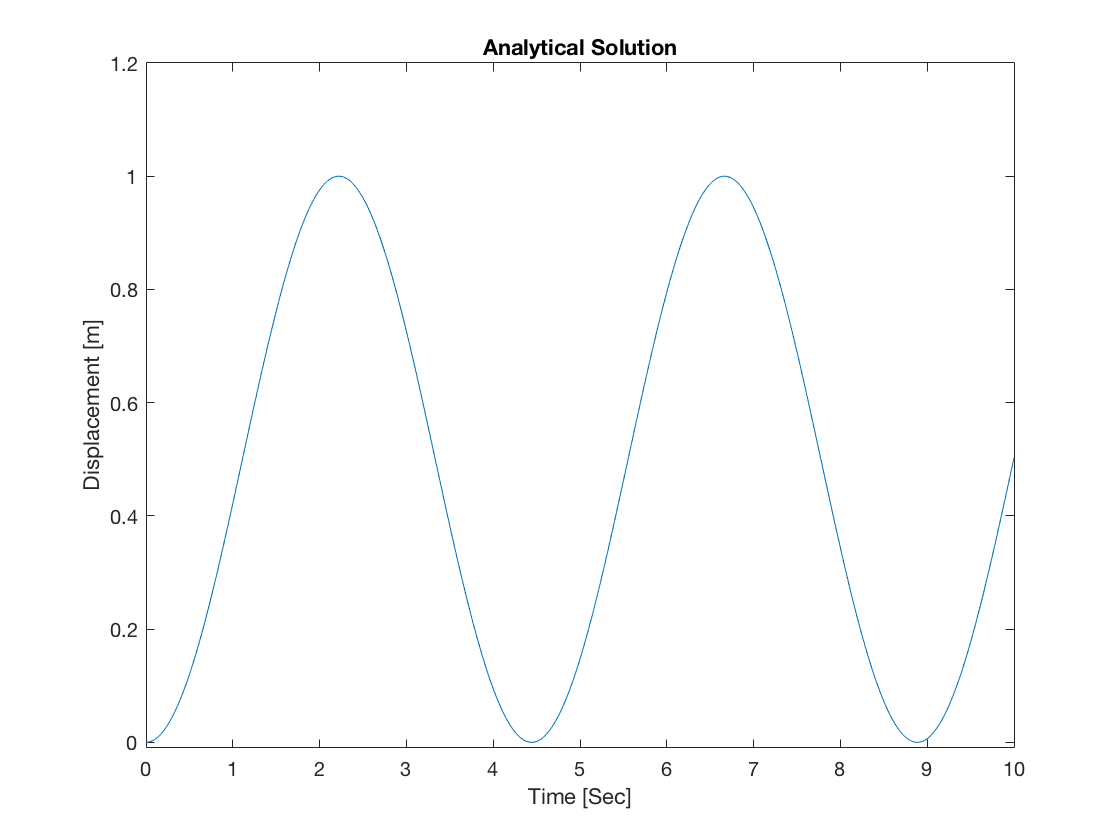

clear all;
clc
t = 0:0.01:10;          % Time period [sec] with increments of 0.01
k = 2;                  % Spring stiffness [N/m]
m = 1;                  % Mass [kg]
omega_n = sqrt(k/m);    % Natural frequency [rad/sec]
x = (1/k) * (1-cos(omega_n*t));

plot(t,x)
axis([0,10,-0.01,1.2]);
xlabel('Time [Sec]');
ylabel('Displacement [m]');
title('Analytical Solution')

***iii) Using Laplace transform in  MATLAB/SIMULINK ***

(1) Laplace transform


$$m\ddot{x}(t)+kx(t)=F(t)$$


Taking Laplace transform with 0 initial displacement and 0 initial velocity 


$$ms^2X(s)+kX(s)=F(s)$$


The transfer function (output/input) can be written as,


$$G(s)=\frac{X(s)}{F(s)}=\frac{1}{ms^2+k}$$


the output X(s) is 


$$X(s)=G(s)*F(s)$$


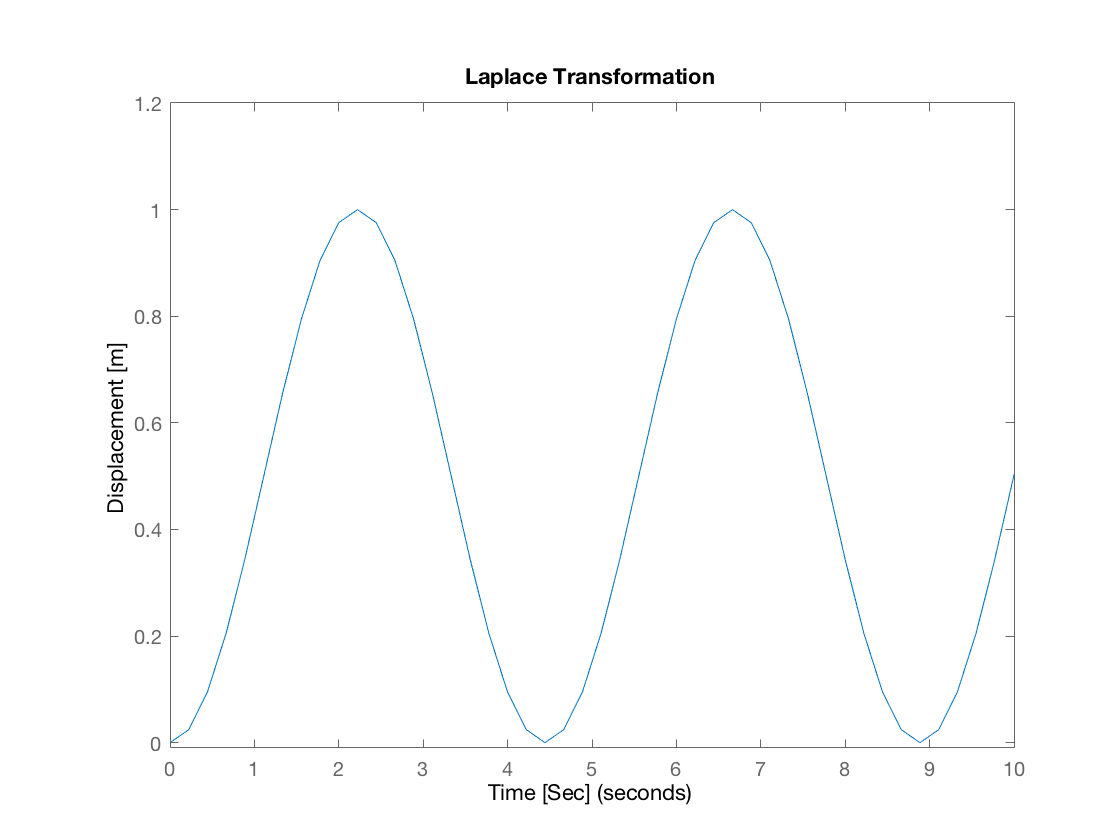

clear all
clc
s = tf('s');
m = 1;
k = 2;
G = 1 / (m*s^2 + k);
step(G)
axis([0,10,-0.01,1.2]);
xlabel('Time [Sec]');
ylabel('Displacement [m]');
title('Laplace Transformation')

(2) SIMULINK

Using MATLAB's SIMULINK, the following block diagram can be constructed to numerically simulate the response of the 1-DoF system to step input.

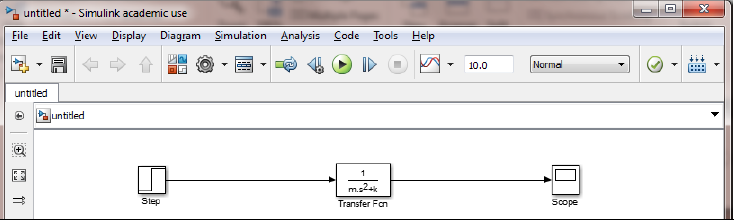

***ii) Numerical simulation use MATLAB***

To use the ODE solvers in MATLAB, the differential equation must be in the state-space form (a set of first-order differential equations). For mass-spring system, we can define the state as,


$$x_1(t)=x(t) \qquad \text{displacement}\\
x_2(t)=\dot{x}(t) \qquad \text{velcocity}$$
 

then the governing equation can be expressed in the form,


$$\dot{x}_1(t)=x_2(t)\\
\dot{x}_2(t)=-\frac{k}{m}x_1(t)+\frac{1}{m}F(t)$$


Using the state-space form govering equation, the following MATLAB codes can be used to solve the ODE numerically,

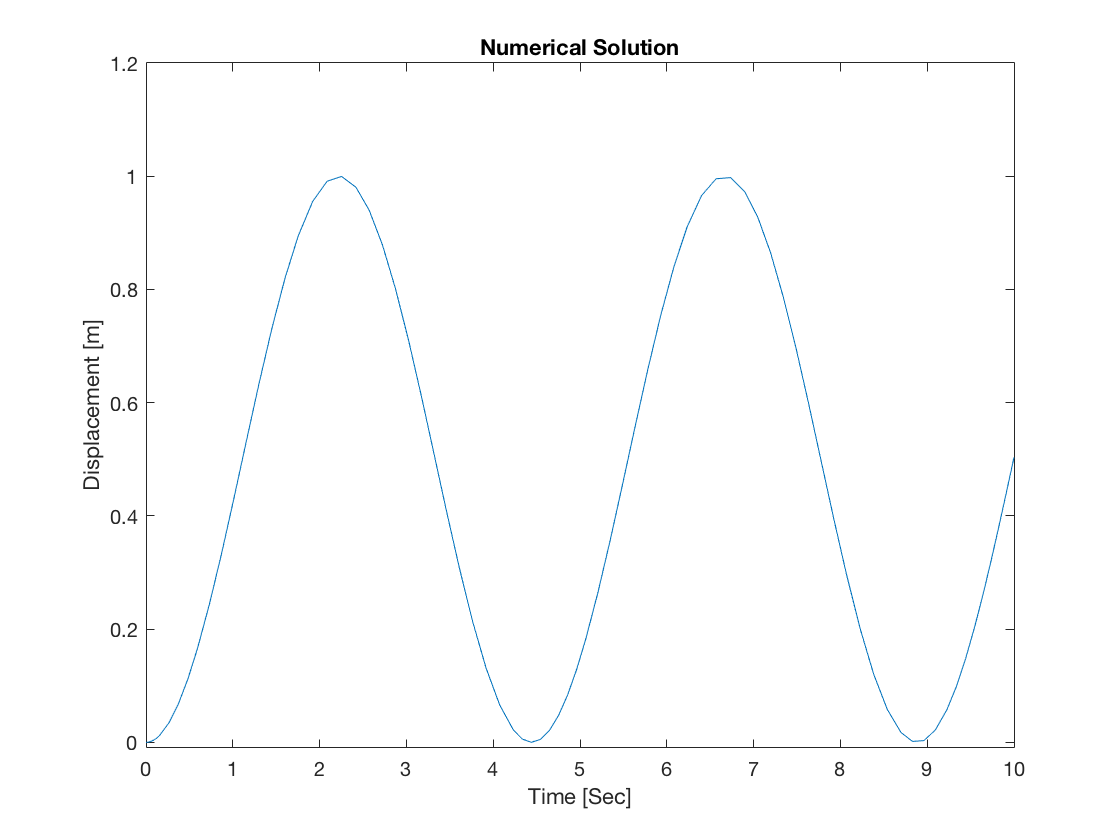

clear all
clc
x_0 = [0 0]; % define initial state = 0
t_0 = 0;     % define initial time = 0
t_f = 10;    % define the final time = 10

[t,x] = ode45(@M_S_ODE,[t_0,t_f],x_0); % use ode45 solver to simulate

plot(t,x(:,1))
axis([0,10,-0.01,1.2]);
xlabel('Time [Sec]');
ylabel('Displacement [m]');
title('Numerical Solution')

function xp = M_S_ODE(t,x)
    xp = zeros(2,1);
    k = 2;
    m = 1;
    F = 1;
    
    xp(1) = x(2);
    xp(2) = -k/m * x(1) + 1/m * F;
end

## **Assignment**

Implement the MALTAB/SIMULINK codes for the mass-spring system example discussed above and determine the displacement time response x(t), use the three methods and compare the polts of each. Show that the responses from i), ii), iii) are identical.

You must submit a PDF document (LastName_FirstName_Studio01.pdf) to your TA before the studio session of the following week. It shall include:

1. A screen shot of your MALTAB/SIMULINK codes for each of the methods.

2. A plot comparing the responses of the mass-spring system derived from the 3 approaches metioned above. 